# 二輪台車シミュレーション用クラス

# 「classTwoWheelGlaphic」の解説

## はじめに

MATLABにて二輪台車シミュレーションを実施する上で、可視化に関わる部分のコードが想定以上に長く、可読性を挙げるにはクラスとして切り出すべきと考えました。

下記では作成したクラス「classTwoWheelGlaphic」の解説をライブクリプトにて行います。

### 代表的な機能

#### １. 下記３つのパラメータをもとに２輪台車のグラフィック描画を行う。

・位置X、Y

・回転角度Theta

#### 2. 下記２つのパラメータについても描画可能。

・速度Velocity、角速度AngVelocity

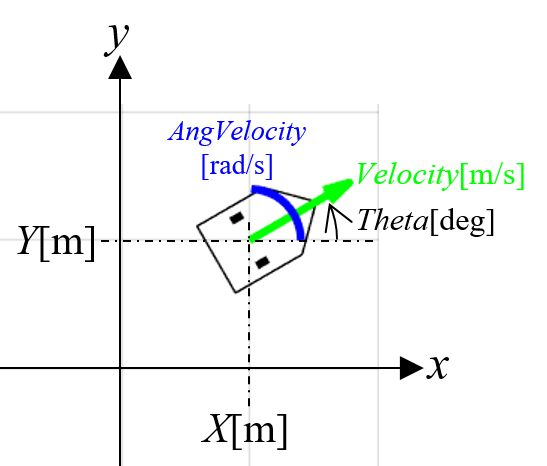

### 注意点

本クラスはあくまでもグラフィック用のものであって、内部にて運動方程式の求解は行っていない。このためクラスの利用にて二輪台車用のパラメータ入力を行うが求解には用いられない。

## 利用方法詳細

### 前準備①二輪台車用パラメータを設定

各定数とマイクロマウスの図面との関係は下記図の通りです。いずれのパラメータもあくまでグラフィック描画用で、

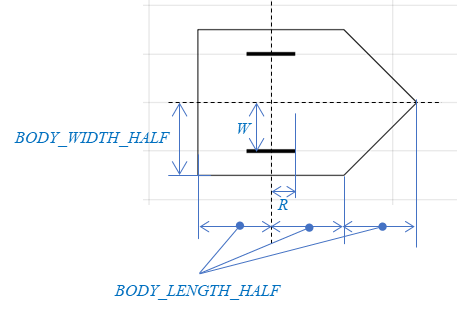

clear all;
close all;

%タイヤ用パラメータ
W = 20e-3; % [m]
R = 5e-3; % [m]

%ボディ用パラメータ
BODY_LENGTH_HALF = 30e-3; % [m]
BODY_WIDTH_HALF = 30e-3; % [m]

### 前準備②シミュレーションおよび動画作成用パラメータを設定

ode45ソルバの設定は下記。

opts = odeset('RelTol',1e-6,'AbsTol',1e-8);

動画の設定は下記。なお、動画作成が不要の場合は省略可能。

frameRate = 20; % [frame/sec]
endTime = 10; % [sec]

Ts = 1 / frameRate;
t1 = [0:Ts:endTime];

## ２輪モデルを作成

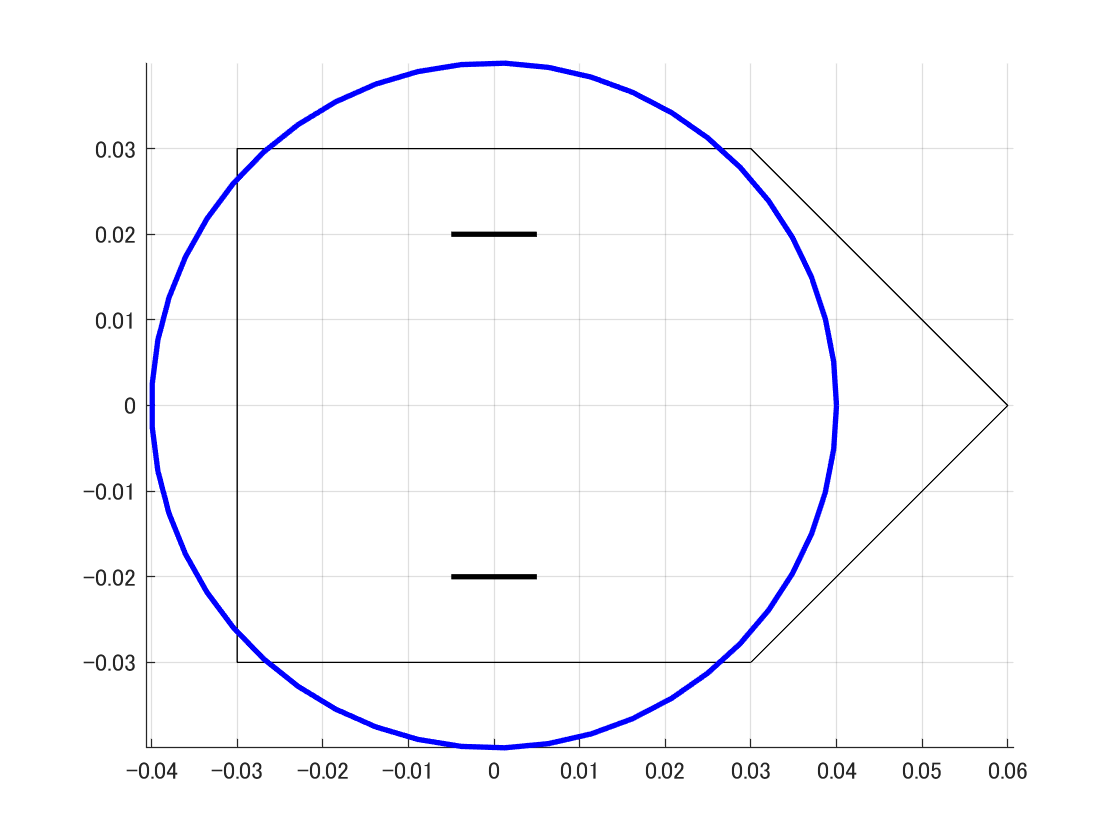

TwoWheel = classTwoWheelGlaphic(R, W, BODY_LENGTH_HALF, BODY_WIDTH_HALF);

## 入力uを規定

u1 = 0.1 + 0.02 * t1;
u2 = 2 * sin(t1 * 2 * pi /endTime);

## ode45で非線形状態方程式を求解

[t,xi]= ode45(@(t,xi) TwoWheelEquation(t,xi,t1,u1,u2),[0 10],[0;0;0],opts);

## 動画作成用に内挿

xi_out=zeros(length(t1),3);
xi_out(:,1) = interp1(t,xi(:,1),t1);
xi_out(:,2) = interp1(t,xi(:,2),t1);
xi_out(:,3) = interp1(t,xi(:,3),t1);
x = xi_out(:,1);
y = xi_out(:,2);
theta = xi_out(:,3);

## figureを調整

Max = max( [max(x) max(y)] ) + 0.2;
Min = min( [min(x) min(y)] ) - 0.2;
axis([Min Max Min Max]);

## フィードフォワードで動かすため、指令値はとりあえずゼロ設定

xref = zeros(size(x));

関数または変数 'x' が認識されません。

yref = zeros(size(y));
hXYrefPoint = plot(0,0);
hXYLog = plot(x(1), y(1),'Color',[1 0 1]);

% 可視化および動画化を関数内にて実施
MakeTwoWheelVideo(Ts, hXYrefPoint, hXYLog, TwoWheel, ...
                        xref, yref, ...
                        x, y, theta, ...
                        u1, u2);